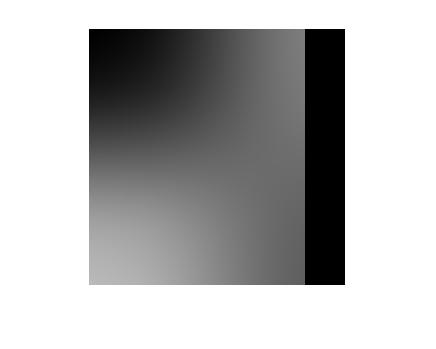

clc
clear all
clf

geometry_number=13500;
root='F:\2023博士课题\dataset\6.13_9_shape_13500_2700\train\';%根目录
root1='left\';%根目录
path_ori_geometory=[root root1 'geometry\'];
% path_ori_geometory=[root 'left\geometry\'];
path_ori_in=[root root1 'grating\'];
path_ori_hf=[root root1 'high_fre_grating\'];
path_ori_out_wrapped_low=[root root1 'phi_wrapped_low\'];
path_ori_out_wrapped_high=[root root1 'phi_wrapped_high\'];
path_ori_out_unwrapped=[root root1 'phi_unwrapped\'];
path_ori_in_no_noisy=[root root1 'grating_no_noisy\'];
path_ori_out_wrapped_low1=[root root1 'phi_wrapped_low_no_noisy\'];
path_ori_out_wrapped_high1=[root root1 'phi_wrapped_high_no_noisy\'];
path_ori_out_unwrapped1=[root root1 'phi_unwrapped_no_noisy\'];

path_ori_k_2=[root root1 'get_k_int\'];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%   测试生成的.mat文件         %%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%\

geometry=load([path_ori_geometory sprintf('%06d', geometry_number),'.mat'],'geometry');


geometry=geometry.geometry;
figure;
imshow(geometry);

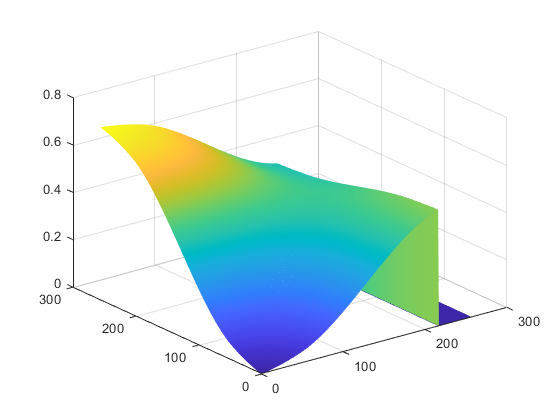

figure;
mesh(geometry);

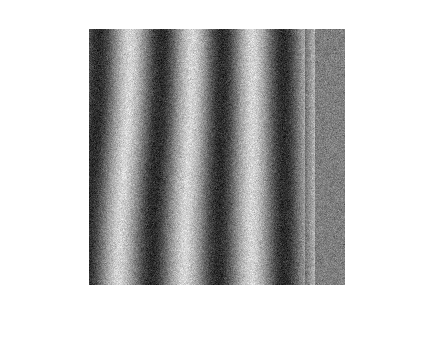

high_fre_grating=load([path_ori_hf sprintf('%06d', geometry_number) '.mat'],'grating_left');
%load载入.mat文件，得到的是个structure类型的数据，需要再等于另外一个变量进行赋值，才会转为矩阵形式
high_fre_grating=high_fre_grating.grating_left;
figure;
imshow(high_fre_grating,[]);

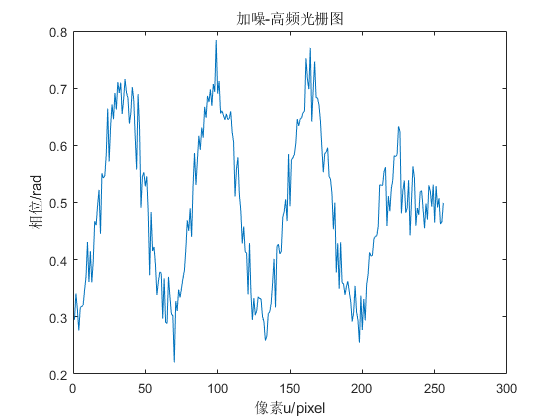

figure;
plot(high_fre_grating(156,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('加噪-高频光栅图')

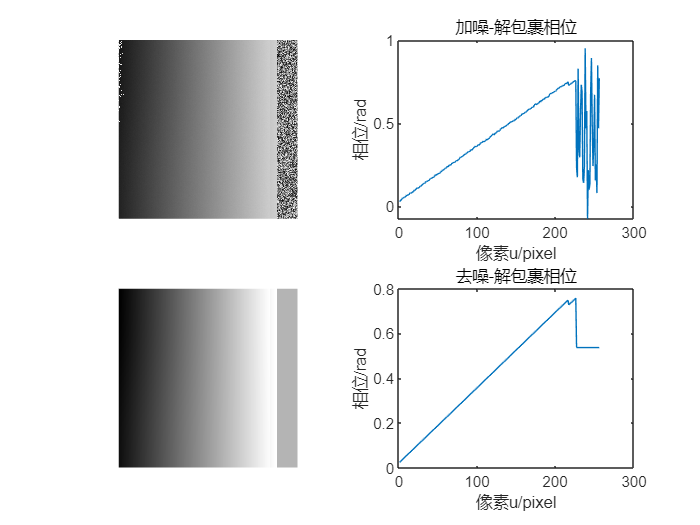


phi_unwrapped=load([path_ori_out_unwrapped sprintf('%06d', geometry_number) '.mat'],'phi_unwrapped');
phi_unwrapped=phi_unwrapped.phi_unwrapped;
figure;
subplot(2,2,1);
imshow(phi_unwrapped,[]);
subplot(2,2,2);
plot(phi_unwrapped(156,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('加噪-解包裹相位')

phi_unwrapped_no_noisy=load([path_ori_out_unwrapped1 sprintf('%06d', geometry_number) '.mat'],'phi_unwrapped');
phi_unwrapped_no_noisy=phi_unwrapped_no_noisy.phi_unwrapped;
subplot(2,2,3);
imshow(phi_unwrapped_no_noisy,[]);
subplot(2,2,4);
plot(phi_unwrapped_no_noisy(126,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('去噪-解包裹相位')

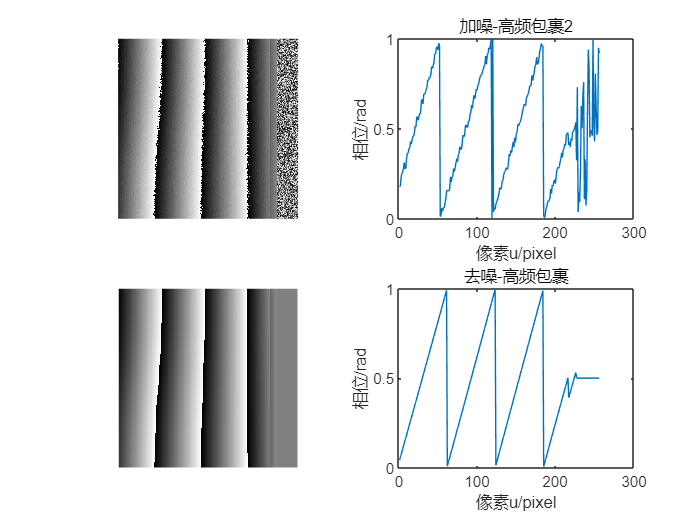



phi_wrapped_high=load([path_ori_out_wrapped_high sprintf('%06d', geometry_number) '.mat'],'phi_wrapped_high');
phi_wrapped_high=phi_wrapped_high.phi_wrapped_high;
figure;
subplot(2,2,1);
imshow(phi_wrapped_high,[]);
subplot(2,2,2);
plot(phi_wrapped_high(210,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('加噪-高频包裹2')

phi_wrapped_high_no_noisy=load([path_ori_out_wrapped_high1 sprintf('%06d', geometry_number) '.mat'],'phi_wrapped_high');
phi_wrapped_high_no_noisy=phi_wrapped_high_no_noisy.phi_wrapped_high;
subplot(2,2,3);
imshow(phi_wrapped_high_no_noisy,[]);
subplot(2,2,4);
plot(phi_wrapped_high_no_noisy(63,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('去噪-高频包裹')

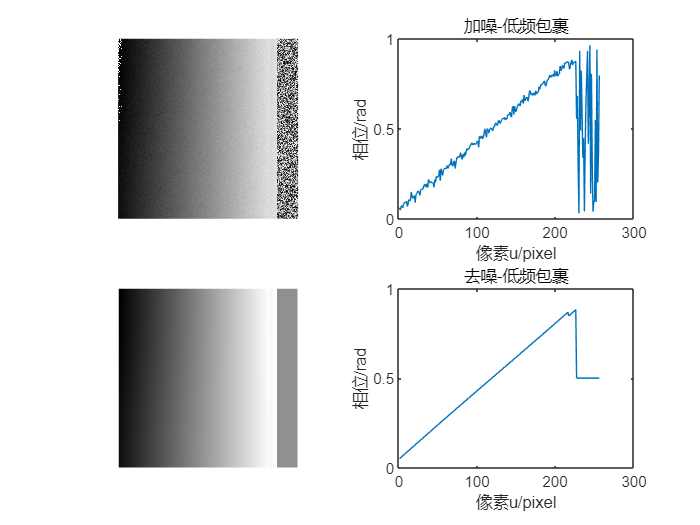



phi_wrapped_low=load([path_ori_out_wrapped_low sprintf('%06d', geometry_number) '.mat'],'phi_wrapped_low');
phi_wrapped_low=phi_wrapped_low.phi_wrapped_low;
figure;
subplot(2,2,1);
imshow(phi_wrapped_low,[]);
subplot(2,2,2);
plot(phi_wrapped_low(220,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('加噪-低频包裹')

phi_wrapped_low_no_noisy=load([path_ori_out_wrapped_low1 sprintf('%06d', geometry_number) '.mat'],'phi_wrapped_low');
phi_wrapped_low_no_noisy=phi_wrapped_low_no_noisy.phi_wrapped_low;
subplot(2,2,3);
imshow(phi_wrapped_low_no_noisy,[]);
subplot(2,2,4);
plot(phi_wrapped_low_no_noisy(210,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('去噪-低频包裹')

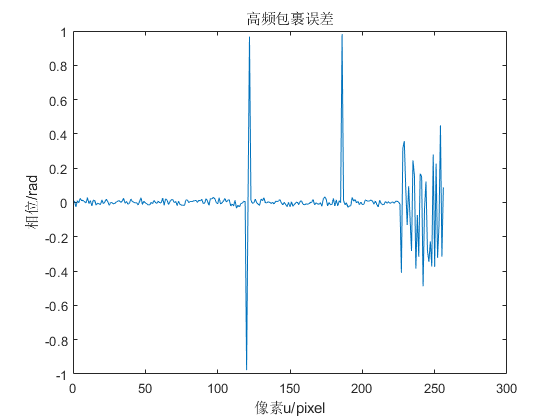




figure;
e1=phi_wrapped_high-phi_wrapped_high_no_noisy;

plot(e1(156,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('高频包裹误差')

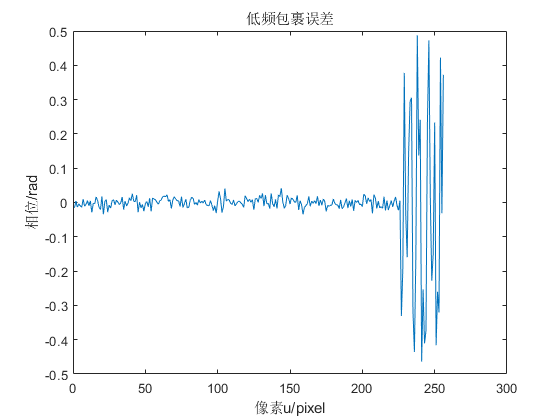



figure;
e2=phi_wrapped_low-phi_wrapped_low_no_noisy;

plot(e2(156,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('低频包裹误差')

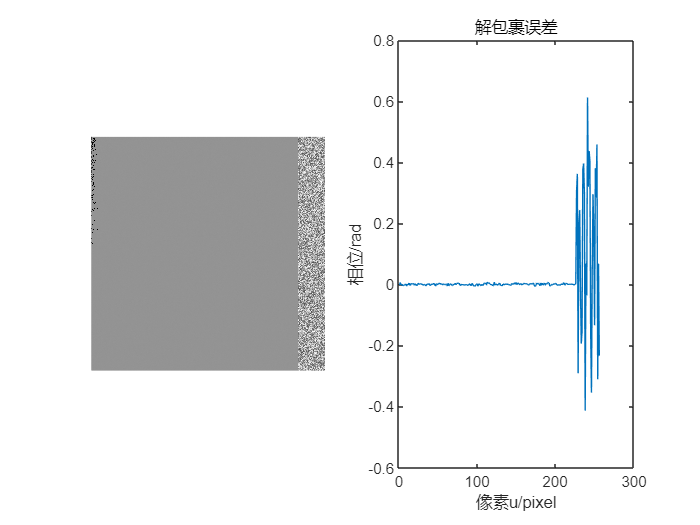



figure;
e3=phi_unwrapped_no_noisy-phi_unwrapped;
subplot(1,2,1);
imshow(e3,[]);
subplot(1,2,2);
plot(e3(156,:));xlabel('像素u/pixel');ylabel('相位/rad'); 
title('解包裹误差')


disp('运行结束')

运行结束


disp([max(max(phi_wrapped_low_no_noisy)),min(min(phi_wrapped_low_no_noisy))]);

    0.8828    0.0039



disp([max(max(phi_wrapped_high_no_noisy)),min(min(phi_wrapped_high_no_noisy))]);

    1.0000    0.0000




disp([max(max(phi_unwrapped)),min(min(phi_unwrapped))]);

    0.9635   -0.1003



disp([max(max(high_fre_grating)),min(min(high_fre_grating))]);

    0.8159    0.1911



disp([max(max(geometry)),min(min(geometry))]);

    0.7263         0



% path_in='E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new1\test\';
% path_out_wrapped_low='E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new1\phi_wrapped_low\';
% path_out_wrapped_high='E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new1\phi_wrapped_high\';
% path_out_unwrapped='E:\liyimingPCL\博士课题\实验记录-源代码+过程\3.14-基本工件几何体仿真\code\new1\phi_unwrapped\';
% 
% [phi_wrapped_low,phi_wrapped_high,phi_unwrapped] = unwrap_mul_fre(4,6,path_in,path_out_wrapped_low,path_out_wrapped_high,path_out_unwrapped) ;
% % disp(['Data saved to ' phi_wrapped_low ' and ' phi_wrapped_high 'and' phi_unwrapped]);
% % disp(['Data saved' ]);
% 
% figure;
% imshow(phi_wrapped_low,[]);
% figure;
% imshow(phi_wrapped_high,[]);
% figure;
% imshow(phi_unwrapped,[]);


% A=load(path1);
% A1=A.phi_wrapped(:,:,1);
% A2=A.phi_wrapped(:,:,2);
% A3=A.phi_wrapped(:,:,3);
% A4=A.phi_wrapped(:,:,4);
% figure;
% imshow(A1,[]);
% figure;
% imshow(A2,[]);
% figure;
% imshow(A3,[]);
% figure;
% imshow(A4,[]);
% figure;plot(A1(350,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% hold on;
% plot(A1(500,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% figure;plot(A2(350,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% hold on;
% plot(A2(500,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% figure;plot(A3(350,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% hold on;
% plot(A3(500,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% figure;plot(A4(350,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% hold on;
% plot(A4(500,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% B=load(path2);
% B1=B.phi_unwrapped(:,:,1);
% 
% figure;
% imshow(B1,[]);
% 
% figure;plot(B1(350,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% hold on;
% plot(B1(500,:)/pi);xlabel('像素u/pixel');ylabel('相位/rad'); 
% 